%% CONSTANTS %%

H = 6.62607004*10^-34; % m2kg/s
C = 299792458; % m/s

%% Sample's Characteristics %%

global a;
global b;
global c;
global atomPositions;

% Unit Cell size, in Angstrom's
a = 29.03*10^-10;
b = 29.03*10^-10;
c = 29.03*10^-10;

% Atomic positions in unit cell
atomPositions = [0,0,0];

%% X-Ray Beam Properties %%

beamkeV = 8.05; %Enter value in keV
lambda = (H*C)/(beamkeV*(6.2415096471204*10^15)^-1); % m

%% XRD %%
% n*lambda = 2*d*sin()

thetaData = [];
planeData = [];
dspace = [];
intensity = [];
F = [];
% Calculate angle for different (hkl) planes
for h = 0:5
    for k = 0:5
        for l = 0:5
            d = dspacing(h,k,l); 

            if lambda/(2*d) <= 1 && lambda/(2*d) >= -1                
                theta = asind(lambda/(2*d));
                
                atoms = zeros(size(atomPositions,1),1);
                for i1 = 1:length(atoms)
                    atoms(i1) = exp(2*pi*1i*(h*atomPositions(i1,1)+k*atomPositions(i1,2)+l*atomPositions(i1,3)));
                end
                f = abs(real(formFactor(4*pi*sind(theta)/(lambda*10^10))*sum(atoms)));
                if f == 0
                    continue;
                end
                
                F = [F; sum(atoms)*formFactor(4*pi*sind(theta)/(lambda*10^10))];
                intensity = [intensity; abs(F(end))^2];
                dspace = [dspace; d];
                thetaData = [thetaData, theta];
                planeData = [planeData; h,k,l];
            end           
        end
    end
end

data = [planeData(2:end,:),2*thetaData(2:end)',dspace(2:end)*10^10,intensity(2:end)];
array2table(data,"VariableNames",{'h', 'k', 'l', '2theta [º]','dspace [A]', 'Intensity'})

ans = 215×6 table
    h    k    l    2theta [º]    dspace [A]    Intensity
    _    _    _    __________    __________    _________

    0    0    1      3.0402         29.03       1055.8  
    0    0    2      6.0825        14.515       1043.3  
    0    0    3      9.1291        9.6767       1023.6  
    0    0    4      12.182        7.2575       997.72  
    0    0    5      15.244         5.806       967.35  
    0    1    0      3.0402         29.03       1055.8  
    0    1    1      4.2999        20.527       1051.6  
    0    1    2      6.8012        12.983       1039.3  
    0    1    3       9.624        9.1801       1019.7  
    0    1    4      12.559        7.0408        994.2  
    0    1    5      15.548        5.6933       964.15  
    0    2    0      6.0825        1

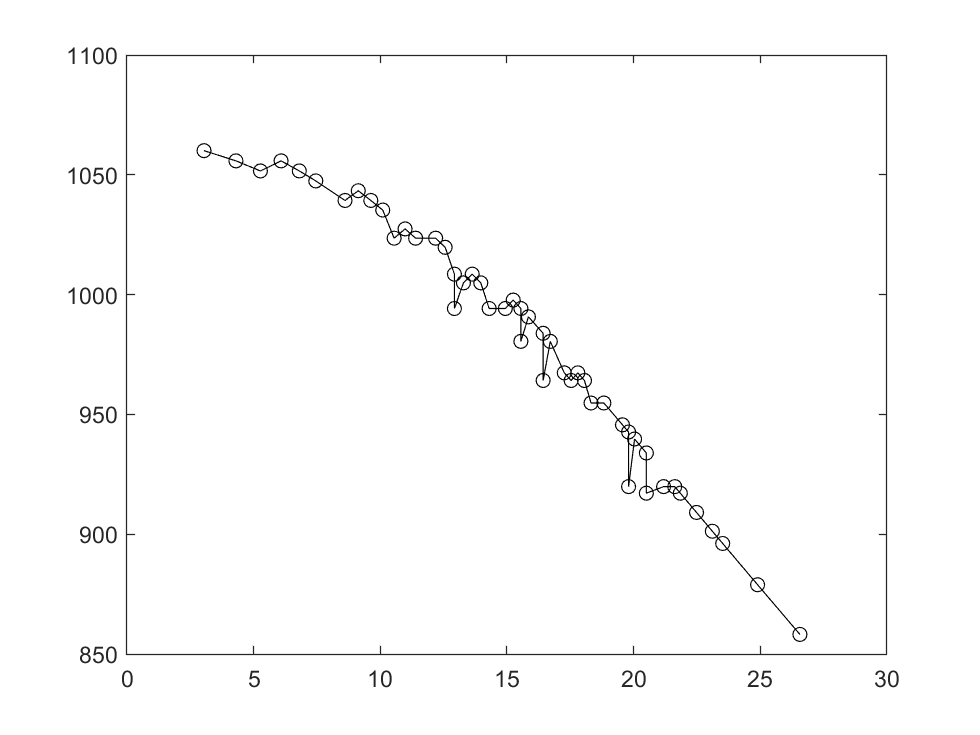

[V,v,~] = unique(thetaData(2:end)*2);

plot(V,intensity(v),'ok-')

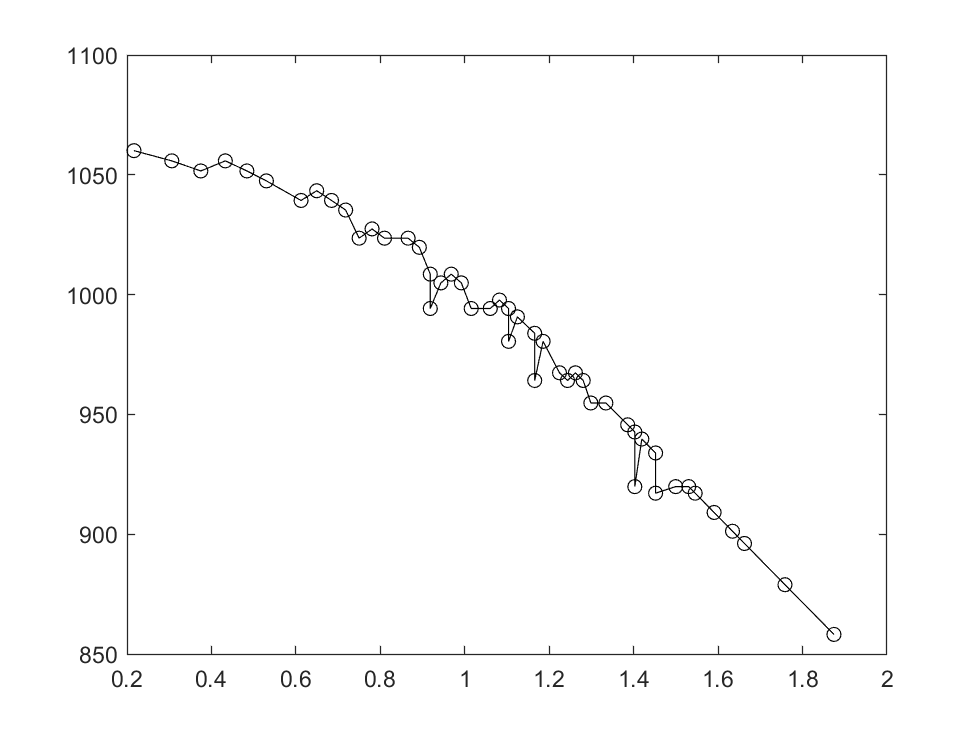

q = (4*pi*sind(thetaData(2:end)))/(lambda*10^10);
[V,v,~] = unique(q);

plot(V,intensity(v),'ok-')

function spacing = dspacing(h1,k1,l1)
    global a;
    global b;
    global c;
    spacing = sqrt((h1^2/a^2+k1^2/b^2+l1^2/c^2)^-1);
end

function f = formFactor(g)
    f = 0;
    ax = [13.338 7.1676 5.6158 1.6735]; %Data for Cu
    bx = [3.5828 0.247 11.3966 64.8126];
    cx = 1.191;
    for idx = 1:4
        f = f + ax(idx)*exp(-bx(idx)*(g/(4*pi))^2)+cx;
    end
end